# Modeling & Simulating Hourly Temperature

This example demonstrates fitting a non-linear temperature model to hourly dry bulb temperatures recorded in the New England region. The temperature series is modeled as a sum of two compoments, a deterministic non-linear function that explains the seasonal or expected temperature for a given hour in a given year and a stochastic component that explains deviations of actual temperature from average values. 

## Import Data

The data set is loaded from a previously created MAT-file. It consist of a vector of serial dates and the corresponding historical recorded temperature.

clear
load Data\elecPrices.mat

% select data of interest
Temp = elecPrices(:,{'Dew_Point','Dry_Bulb'});
tail(Temp)

ans = 8×2 timetable
       Date       Dew_Point    Dry_Bulb
    __________    _________    ________

    11/30/2018       29           36   
    11/30/2018       30           35   
    11/30/2018       30           35   
    11/30/2018       30           35   
    11/30/2018       30           35   
    11/30/2018       29           34   
    11/30/2018       29           34   
    11/30/2018       29           33   


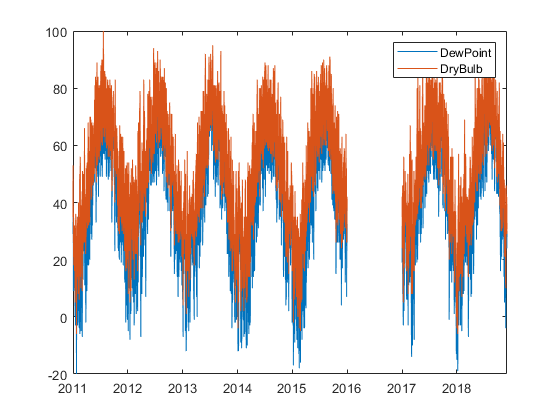

plot(Temp.Date,[Temp.Dew_Point,Temp.Dry_Bulb])
legend('DewPoint','DryBulb')

Note the missing year of temperature data from 2016 to 2017.  We will need to account for this during the estimation of the model.

## Seasonal Component (Deterministic)

The deterministic or expected temperature component is modeled with a sum of sines model, motivated by the physical nature of temperature and periodicities observed in the data. Curve Fitting toolbox is used to estimate the parameters of the model. The Statistics Toolbox function NLINFIT can also be used to estimate the model parameters.

% Compute mean (yearly average) and remove it from the series
validIndices = find(~isnan(Temp.Dry_Bulb));
m = mean(Temp.Dry_Bulb(validIndices))

m = 50.8951

drybulb0 = Temp.Dry_Bulb(validIndices) - m;

% Fit double-sine model
numericDates = datenum(Temp.Date(validIndices));
model = fit(numericDates, drybulb0, 'sin2')

model =      General model Sin2:
     model(x) =  a1*sin(b1*x+c1) + a2*sin(b2*x+c2)
     Coefficients (with 95% confidence bounds):
       a1 =       22.77  (22.66, 22.87)
       b1 =     0.01734  (0.01733, 0.01734)
       c1 =       -1559  (-1563, -1555)
       a2 =     0.01598  (-0.08931, 0.1213)
       b2 =       5.488  (5.48, 5.495)
       c2 =       2.264  (-5621, 5626)

## Visualize Model Accuracy

Analyze the fit results visually with a custom plot. The two axes in the plots are linked which greatly enables visual exploration of the data. Also note that the date ticks on the X-axes are dynamic with respect to zooming and panning.

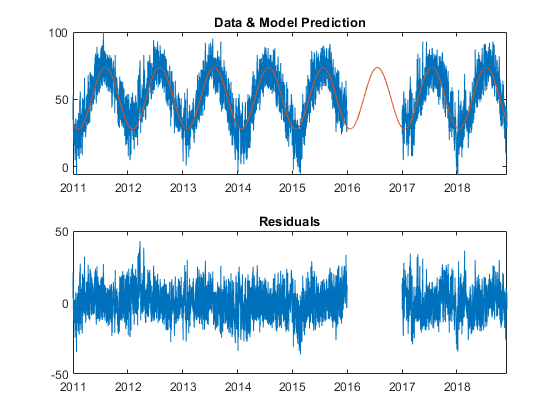

Temp.pred = model(datenum(Temp.Date)) + m;
res = Temp.Dry_Bulb - Temp.pred;
subplot(2,1,1)
plot(Temp.Date,[Temp.Dry_Bulb Temp.pred])
title('Data & Model Prediction')

subplot(2,1,2)
plot(Temp.Date, res)
title('Residuals')

disp(['Mean Absolute Error: ' num2str(mean(abs(res))) ' degrees F']);

Mean Absolute Error: NaN degrees F


## Analyze Serial Correlation in Residuals

One of the features apparent in the above plot is that the residuals are serially correlated. This is expected as above average temperatures are likely to follow above average temperatures. This serial correlation can be explicitly measured. Here, the functions AUTOCORR and PARCORR are used to display the autocorrelation and partial autocorrelation in the series.

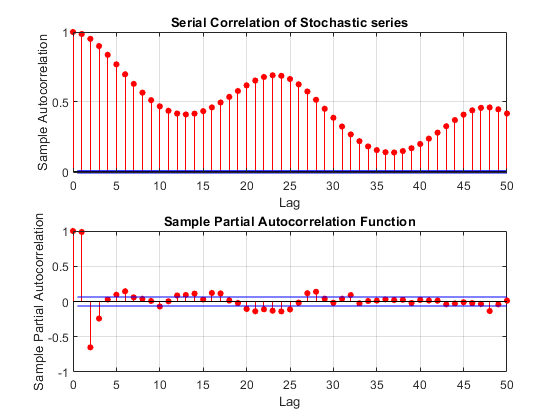

figure;
subplot(2,1,1);
autocorr(res,50);
title('Serial Correlation of Stochastic series');
subplot(2,1,2);
parcorr(res(1:1000),50);

## Modeling the Stochastic Component with a ARIMX model

One could choose to model the random component a mean reverting drift SDE. However, because of the seasonality, we will use an auto-regressive model with seasonal lags.

lags = [1 2 3 4 23 24 25 47 48 49];
%% Estimate an ARIMAX Model of time series Dry_Bulb with exogenouse factor the avergage temperature (pred)
ARIMAX_Dry_Bulb = arima('Constant',NaN,'ARLags',lags,'D',0,'MALags',[],'Distribution','Gaussian');
validIndices = find(~any(isnan([Temp.Dry_Bulb,Temp.pred]),2));
preSampleNumber = ARIMAX_Dry_Bulb.P;
preSampleResponse = Temp.Dry_Bulb(validIndices(1:preSampleNumber));
estimateResponse = Temp.Dry_Bulb(validIndices(preSampleNumber+1:end));
pred = Temp.pred(validIndices);
ARIMAX_Dry_Bulb = estimate(ARIMAX_Dry_Bulb,estimateResponse,'Y0',preSampleResponse,'X',pred,'Display','off');
summarize(ARIMAX_Dry_Bulb)

 
   ARIMAX(49,0,0) Model (Gaussian Distribution)
 
    Effective Sample Size: 60551
    Number of Estimated Parameters: 13
    LogLikelihood: -85648.4
    AIC: 171323
    BIC: 171440
 
                  Value       StandardError    TStatistic      PValue   
                __________    _____________    __________    ___________

    Constant    -0.0081649       0.013797       -0.5918          0.55399
    AR{1}            1.317       0.003305         398.5                0
    AR{2}         -0.15082      0.0056532       -26.679       8.239e-157
    AR{3}         -0.20443       0.006037       -33.863       2.334e-251
    AR{4}          0.01574      0.0034436         4.571       4.8547e-06
    AR{23}          0.1394      0.0035702      

## Analyze Residuals of Regression for Serial Correlation

The residuals from the regression should now be mostly serially uncorrelated. 

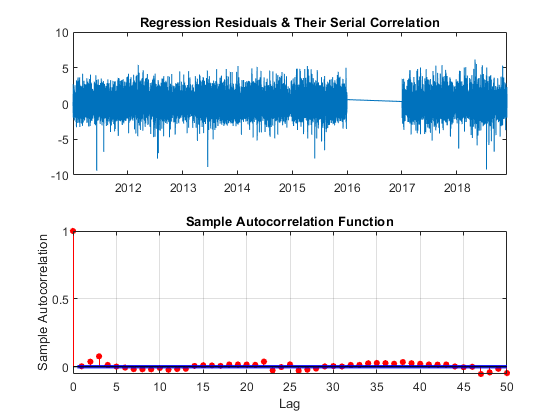

res = infer(ARIMAX_Dry_Bulb,estimateResponse,'Y0',preSampleResponse,'X',pred);
figure;
subplot(2,1,1);
dates = Temp.Date(validIndices);
plot(dates(preSampleNumber+1:end), res);
title('Regression Residuals & Their Serial Correlation');
subplot(2,1,2);
autocorr(res,50);

## Model Estimate

Put the different components together to see how the model fits the data.  We will need to forecast the period for 2016 first using the data up to 2016.

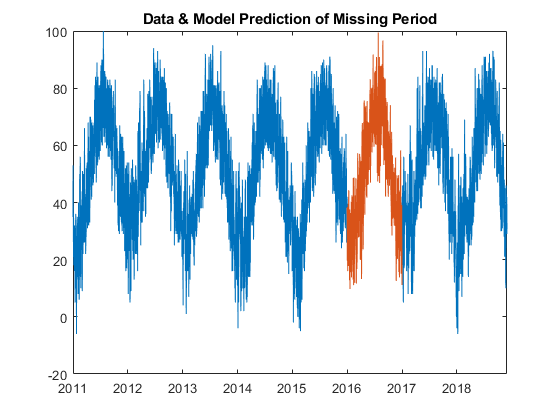

Indicies2016 = find(ismissing(Temp.Dry_Bulb));
preSampleIndicies = (Indicies2016(1)-preSampleNumber):Indicies2016(1)-1;
Temp2016= simulate(ARIMAX_Dry_Bulb,length(Indicies2016),'Y0',Temp.Dry_Bulb(preSampleIndicies),'X',Temp.pred(preSampleIndicies(1):Indicies2016(end)));
figure
plot(Temp.Date,Temp.Dry_Bulb, Temp.Date(Indicies2016), Temp2016)
title('Data & Model Prediction of Missing Period')

Now add in a simulation of the entire series by putting the Temp2016 data into the Temp `timetable`

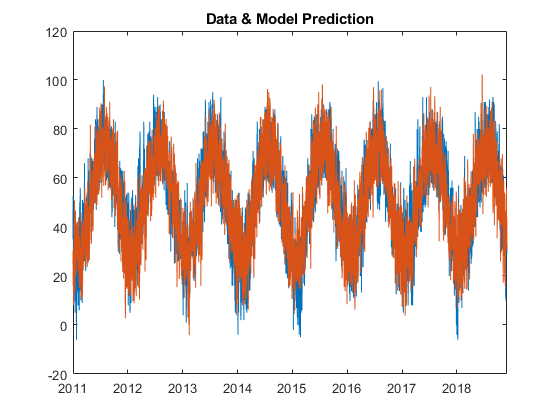

Temp.Dry_Bulb(Indicies2016) = Temp2016;
simTemp = simulate(ARIMAX_Dry_Bulb,length(Temp.Dry_Bulb),'Y0',Temp.Dry_Bulb(1:preSampleNumber),'X',Temp.pred);

figure
plot(Temp.Date,[Temp.Dry_Bulb, simTemp])
title('Data & Model Prediction')

## Summary of model

The temperature model can now be defined by,

- The mean temperature "m"

- The sinusoidal model "model"

- ARIMAX parameters and lags

tempModel = struct('m', m, 'sinmodel', model, 'reglags', lags, 'arimax', ARIMAX_Dry_Bulb,'lastDate',Temp.Date(end),'Freq','hourly');
save SavedModels\TemperatureModel.mat -struct tempModel